# Scanned OCT phase-only compensation

In this script we are testing idea of two-step phase only compenstation aberration in scanned OCT.

Load data with low aberrations

addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\functions\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\HelpFun\','-end')

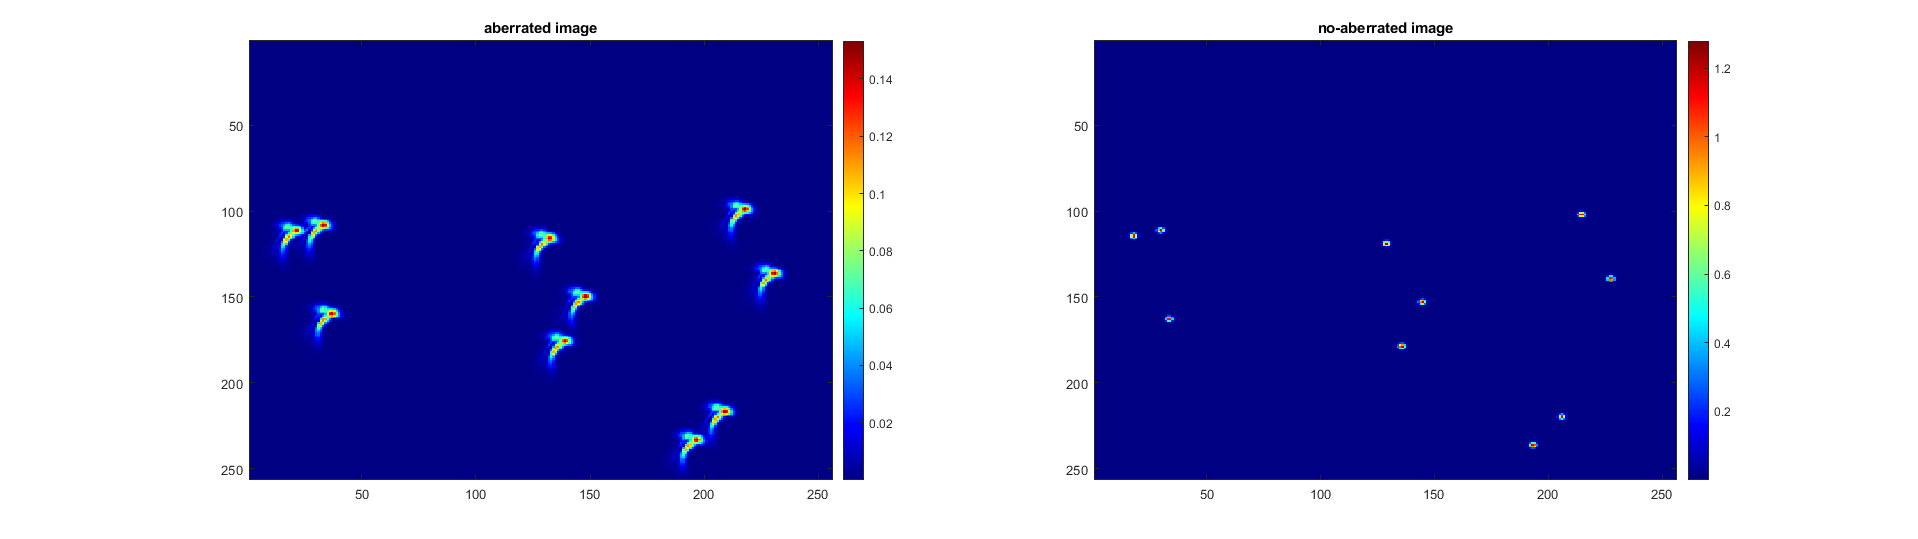



load('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\modelling_real_abb\OCT10_Se_lNa256.mat')
E = L2(:,:,51);
load('C:\MatkivskiyV\science\article8\ab_comp_matlab\data\modelling_real_abb\OCT10_Bez.mat')
E0 = L2(:,:,51);
h0 = figure;
subplot(1,2,1)
imagesc(abs(E)); colormap(jet); colorbar;
title('aberrated image');
subplot(1,2,2)
imagesc(abs(E0)); colormap(jet); colorbar;
title('no-aberrated image');

set(h0,'Units','normalized','position',[0 0 1 .5])

Inserted the dot into new array in the center

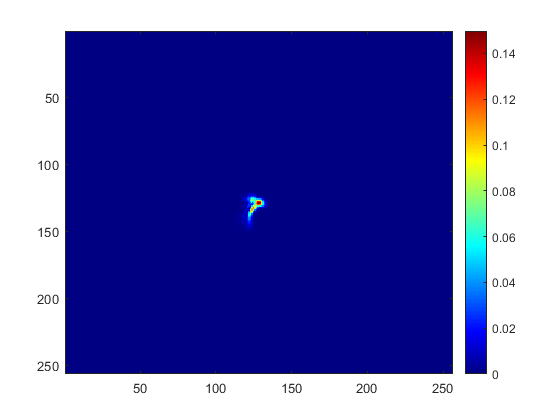

E2 = zeros(size(E));
E2(129-16:129+20,129-16:129+15) = E(116-16:116+20,133-16:133+15);
figure();
imagesc(abs(E2)); colormap(jet); colorbar;

## Generate parameters for fields calculations

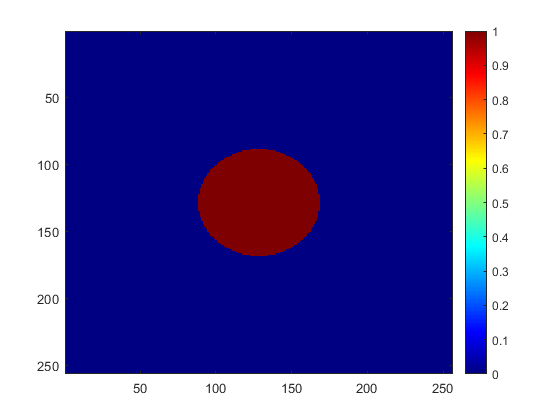

N = 256;
Global_constants = zeros(10,1);
lam = 0.85*10^-3; 
k = 2*pi/(lam); 
dx = 300/256*10^-3;
L = dx*N;
[x,y] = meshgrid(-L/2:dx:L/2-dx);
x = x + dx/2 ; 
y = y + dx/2;
r = sqrt( x.^2 + y.^2 ); 
kz = rphase3(dx,L,k);
Raperture = 40*dx;
is_in_circle40 = circ(r/Raperture);
imagesc(is_in_circle40); colorbar; %radius of the lens - one of paramiters of generation

## Aberration compensetion for one dot into two steps

Calculates fields in lens plane. dz = 200$\mu \mathrm{m}$. plh( ... ) - is function for field calculation

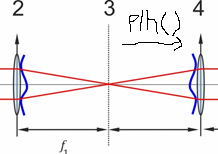

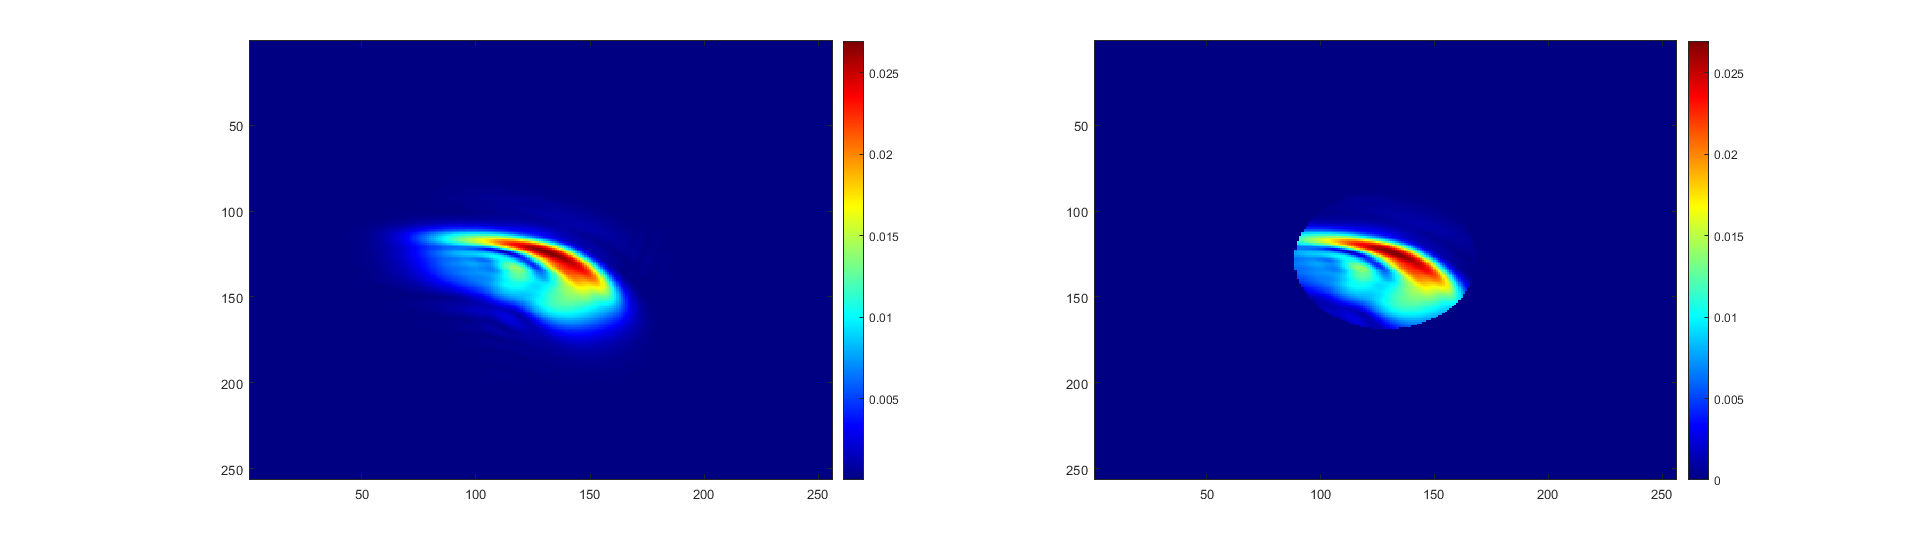

dz = -0.2;
El = plh( -dz, kz, r, E2, lam, dx );
h = figure();
subplot(1,2,1)
imagesc(abs(El)); colormap(jet); colorbar;
subplot(1,2,2)
imagesc(abs(El).*is_in_circle40); colormap(jet); colorbar;

set(h,'Units','normalized','position',[0 0 1 .5])

Load aberration phase

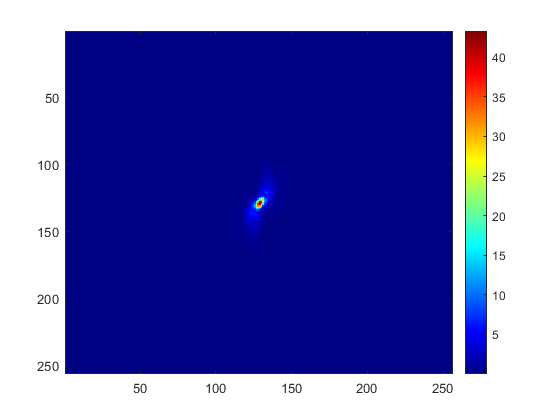

imagesc(abs(FTS(abs(El)))); colormap(jet); colorbar;



h2 = figure;
load("C:\MatkivskiyV\science\article8\ab_comp_matlab\data\modelling_real_abb\Se_lNa256.mat");
Fi = Se_lNa256; 
clear Se_lNa256
imagesc(Fi); colormap(jet); colorbar;

We get the corrected field in lens plane for testing. We can see, that aberrations are partially compensated. 

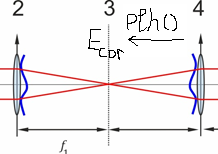

E3 = El.*exp(1j*Fi); %El - field in lens plane
Ecor = plh( dz, kz, r, E3, lam, dx ); %recalculate in initial plane
h3 = figure();
subplot(1,2,1)
imagesc(abs(Ecor(129-32:129+31,129-32:129+31))); title('corrected image'); colormap(jet); colorbar; caxis([0 0.24]);
subplot(1,2,2)
imagesc(abs(E2(129-32:129+31,129-32:129+31))); title('initial image'); colormap(jet); colorbar; caxis([0 0.24]);
set(h3,'Units','normalized','position',[0 0 1 .5])

lens phase $\psi =\frac{{\textrm{kr}}^2 }{2F}$, there $F$- is lens focus. But, I think, it's don't usable here

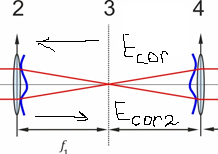

F = 0.2;
Psi = k*r.^2/2/F;
E4 = E3.*exp(-1j*Psi);
E5 = plh( dz, kz, r, Ecor, lam, dx );
figure()
imagesc(abs(E5)); colormap(jet); colorbar;
E6 = E5.*exp(1j*rot90(Fi,2));
E7 = plh( -dz, kz, r, E6, lam, dx );
figure();
imagesc(abs(E7(129-32:129+31,129-32:129+31))); colormap(jet); colorbar; caxis([0 0.24]);
title('second correction of image');

**Unfortunately, it's don't work((**

------------------